# The relationship between accuracy and RTs in color naming and color categorization

addpath('/Users/ksiuda/Dropbox (PICNIC Lab)/Kasia/Colors/color_connectivity/behavioral_corelates')
load('RDS_CTRL_18.mat')

T(T.Sujet_Number==1, :)=[];
T(T.No_Bloc==1 | T.No_Bloc==3, :)=[];



Compute and compare subject-wise variance for ACC and RT in CC and CN

[subject_task_id, subject, task] = findgroups(T.Sujet_Number, T.Task_Type);
RT = splitapply(@mean, T.RT, subject_task_id)

RT =     2.1099
    1.0233
    2.3682
    1.0912
    1.1683
    0.9979
    2.2568
    0.9302
    1.1702
    1.2010


ACC = splitapply(@mean, T.Accuracy,  subject_task_id)

ACC =     0.8344
    1.0000
    0.8662
    1.0000
    0.8917
    0.9936
    0.9045
    1.0000
    0.8790
    0.9936


ans =     1.2985    2.0000
    0.8963    2.0551
    0.8963    2.1653
    1.0000    2.0000
    1.1037    2.0704
    1.1990    2.2111
    1.0995    2.1037
    0.8963    1.9296
    0.8963    1.7889
    1.0704    1.9449


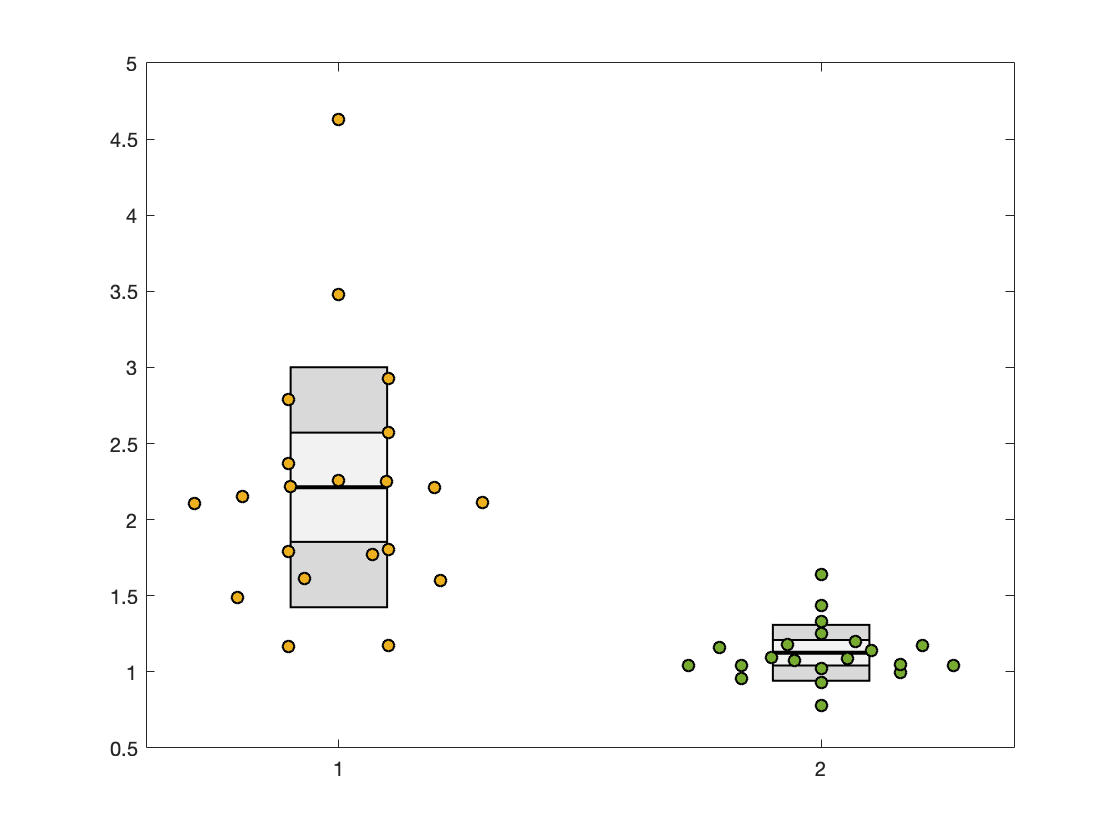

T2 = table(subject, task, RT, ACC);

UnivarScatter([T2.RT(strcmp(T2.task, 'CC')),T2.RT(strcmp(T2.task, 'CN'))])

vartest2(T2.RT(strcmp(T2.task, 'CC')),T2.RT(strcmp(T2.task, 'CN')))

ans = 1

ans =     1.2111    1.7889
    1.0000    2.2111
    1.0000    2.2493
    1.1990    1.9296
    1.0000    1.8338
    0.9296    2.1662
    0.8963    1.7532
    0.7015    1.6676
    1.0000    2.0704
    1.2985    2.2468


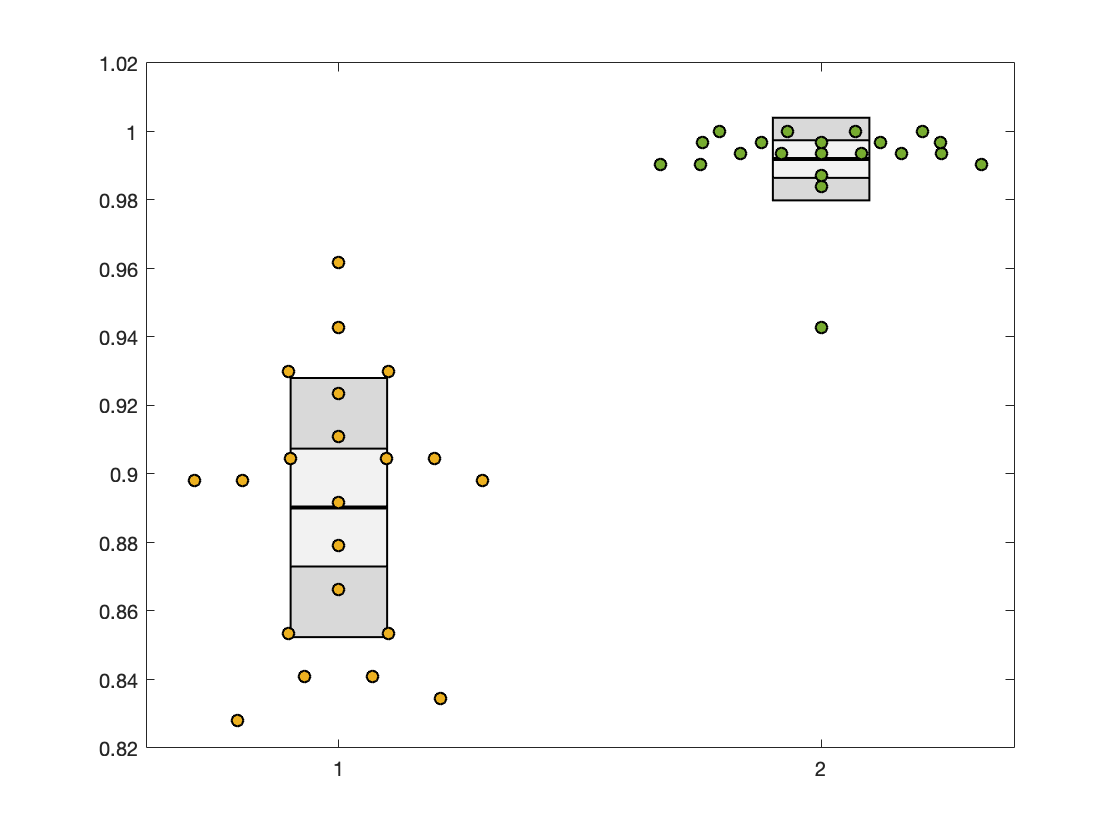


UnivarScatter([T2.ACC(strcmp(T2.task, 'CC')),T2.ACC(strcmp(T2.task, 'CN'))])

vartest2(T2.ACC(strcmp(T2.task, 'CC')),T2.ACC(strcmp(T2.task, 'CN')))

ans = 1

[h,p,ci,stats] = vartest2(T2.RT(strcmp(T2.task, 'CN')),T2.ACC(strcmp(T2.task, 'CN')))

h = 1

p = 3.8545e-19

ci =    93.9582
  570.6722


stats = struct with fields:
    fstat: 231.5585
      df1: 20
      df2: 20


var(T2.RT(strcmp(T2.task, 'CN')))

ans = 0.0337

var(T2.ACC(strcmp(T2.task, 'CN')))

ans = 1.4566e-04